# Projet M2 AURO EKF-SLAM

clc
clear all
close all

## Creation de la carte

La carte est composée de 8 amers dont le robot ne connait pas l'emplacement a priori. Nous allons créer une matrice 2x8 contenant la l'abscisse et l'ordonnnées de la position de chaque amer.


% Matrice contenant les position (X,Y) de chaque amer
Lm=[3, 5, 7, 9, 3, 5, 7, 9 ; 4, 4, 4, 4, 2, 2, 2, 2]

Lm =      3     5     7     9     3     5     7     9
     4     4     4     4     2     2     2     2


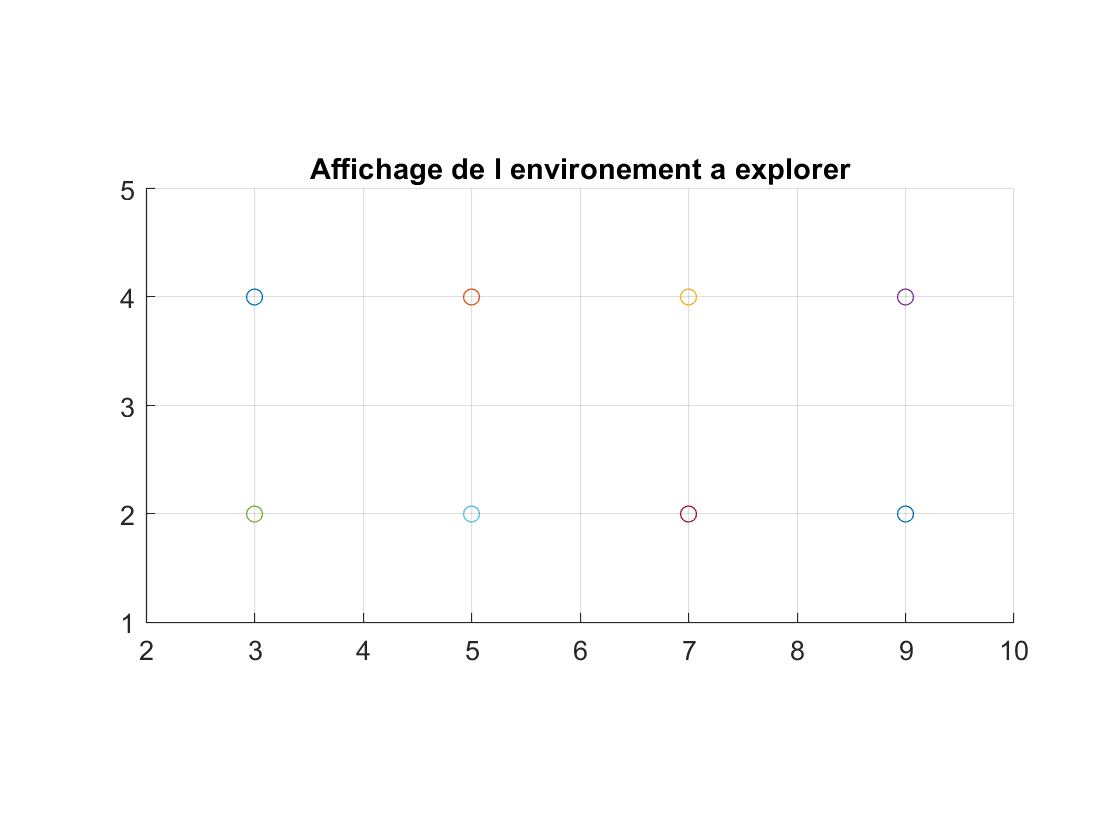


% Affichage de la carte
for k = 1 : length(Lm)
    scatter(Lm(1,k),Lm(2,k))
    title("Affichage de l environement a explorer")
    axis equal
    xlim([2 10])
    ylim([1 5])   
    hold on
    grid on
end
hold off

## Creation d un vecteur de commande

Le vecteur Uk contient la commande pour chaque instant k la [(TauXk,TauYk)',Rhok]'

for i=1:9
    Uk(:,i)=[i;0;0] 
end 

Uk =      1
     0


Uk =      1     2
     0     0


Uk =      1     2     3
     0     0     0


Uk =      1     2     3     4
     0     0     0     0


Uk =      1     2     3     4     5
     0     0     0     0     0


Uk =      1     2     3     4     5     6
     0     0     0     0     0     0


Uk =      1     2     3     4     5     6     7
     0     0     0     0     0     0     0


Uk =      1     2     3     4     5     6     7     8
     0     0     0     0     0     0     0     0


Uk =      1     2     3     4     5     6     7     8     9
     0     0     0     0     0     0     0     0     0


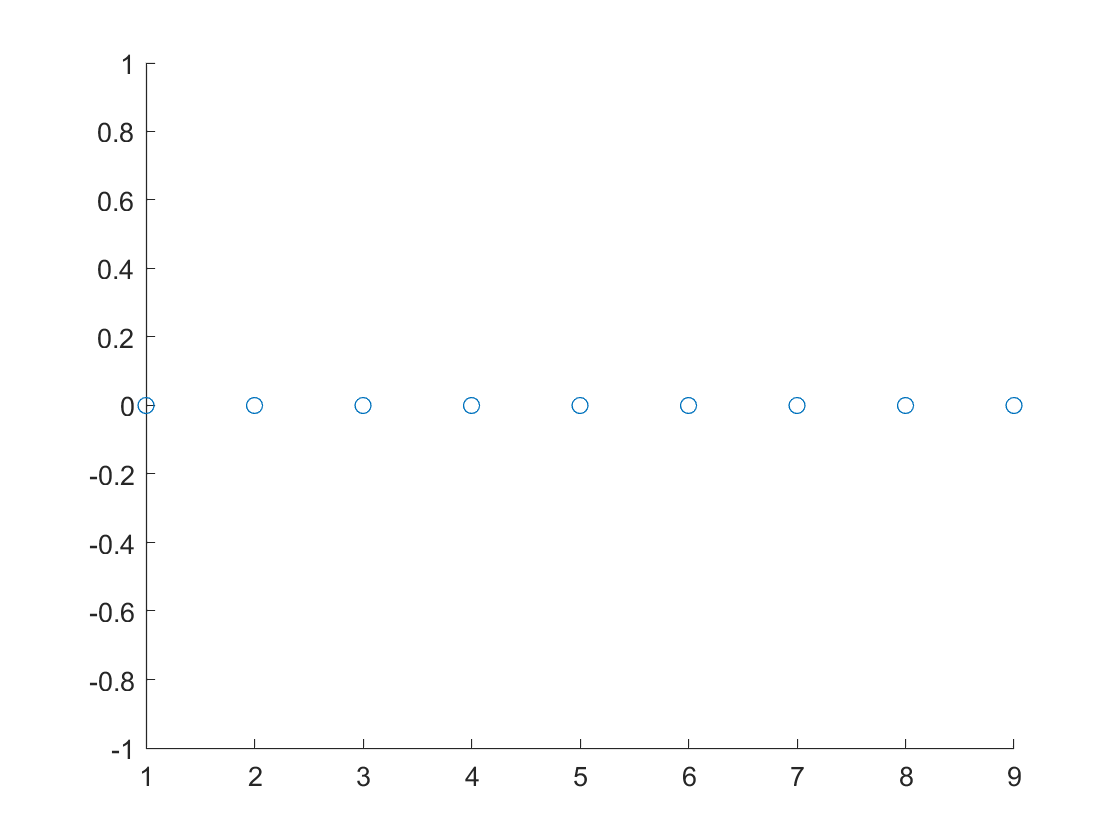


Uk(:,10)=[0;]

for i=11:18
    Uk(:,i)=[i;0;0] 
end


## Modele cinematique du robot non-holonome

Le modèle espace Espace d'Etat reprèsente une dynamique entachée d'un bruit blanc.